# ASSIGNEMENT 1 -- AEROELASTICITY

clear; clc;

# Aeroelastic coefficients used for the subsequent calculations

This section introduces the main coefficients derived previously and required for the remainder of the aeroelastic analysis.  

The objective is not to repeat the full derivation, but rather to define, in a compact and reusable form, the intermediate quantities that will be used later for:

- the computation of the divergence dynamic pressure q_D

- the construction of the global aeroelastic matrix,

- and the evaluation of the control effectiveness E_C.

Whenever a coefficient is introduced numerically, its symbolic expression is also recalled for consistency with the analytical derivation.

### Numerical data

The following numerical values are taken from the statement:

EJ        = 1e7;      % [N.m^2]
GJ        = 1e6;      % [N.m^2]
EA        = 1e8;      % [N]
CL_alpha  = 2*pi;     % [-]
CMAC_beta = -0.1;     % [-]
b         = 14;       % [m]
c         = 1;        % [m]
e         = c/4 ;     % [m]
b_a       = 2.5;      % [m]
gamma_deg = 15;       % [deg]
CL_beta   = pi;       % [-]

Some additional geometric parameters are required by the model but are not given explicitly in the provided numerical table. They are therefore introduced separately and may be adjusted later depending on the selected configuration.

#### Additional geometric parameters

The reduced aeroelastic model also depends on the following geometric quantities:

- z_A : vertical distance entering the strut geometry,

- x_B : chordwise position of the strut attachment point. (This quantity will be a parameter later)

Since these quantities are not specified in the numerical table, they are defined here as explicit model parameters.

% Keep a value for z_A
z_A = 2.0;    % [m]

### Aerodynamic stiffness matrix

The aerodynamic stiffness matrix of the wing is written as

K_A1 = (c*b/4) * CL_alpha;
K_A2 = (e*c*b/3) * CL_alpha;

K_A = [0,   K_A1;
       0,   K_A2];

It is useful to isolate K_A1  and K_A2 explicitly, since both coefficients appear directly in the divergence condition.

### Aileron generalized load vector

The aileron contribution is introduced through the generalized aerodynamic load vector

F_a1 = (c/b) * CL_beta * (b^3 - (b-b_a)^3) / (3*b);
F_a2 = (c/b) * (e*CL_beta + c*CMAC_beta) * (b^2 - (b-b_a)^2) / 2;

F_a = [F_a1;
       F_a2];

These two terms will later be used in the expression of the generalized torsional displacement, and therefore in the control effectiveness formula.

### Structural stiffness matrix

The total structural stiffness matrix is written in the form

K_S11 = @(gamma, x_B) ...
    4*EJ/b^3 + EA*z_A^3/b^4 * (cos(gamma)^4 / sin(gamma));

K_S12 = @(gamma, x_B) ...
   -EA*z_A^2 * cos(gamma)^3 * x_B / b^3;

K_S22 = @(gamma, x_B) ...
    GJ/b + EA * sin(gamma) * cos(gamma)^2 * z_A * x_B^2 / b^2;

K_S = @(gamma, x_B) [ ...
    K_S11(gamma, x_B),   K_S12(gamma, x_B);
    K_S12(gamma, x_B),   K_S22(gamma, x_B) ...
];

The term K_S1 combines the wing bending stiffness and the strut-induced contribution. The coefficient K_S12 represents the bending–torsion coupling induced by the strut geometry. Finally, K_S2  gathers the torsional stiffness of the wing together with the additional contribution due to the strut.

## Divergence dynamic pressure

q_D = @(gamma, x_B) ...
    (K_S11(gamma, x_B) * K_S22(gamma, x_B) - K_S12(gamma, x_B)^2) ...
    / ...
    (K_S11(gamma, x_B) * K_A2 - K_S12(gamma, x_B) * K_A1);

#### Total aeroelastic matrix

For later use, the global reduced aeroelastic matrix is introduced as

% Total aeroelastic matrix
K_TOT = @(gamma, x_B, q) ...
    K_S(gamma, x_B) - q * K_A;

% Determinant of total aeroelastic matrix
det_KTOT = @(gamma, x_B, q) ...
    det(K_TOT(gamma, x_B, q));

## Control effectiveness

The control effectiveness is written as

E_C = @(gamma, x_B, q) ...
    1 ...
    + q * (b/b_a) * (CL_alpha/CL_beta) ...
    * (K_S11(gamma, x_B) * F_a2 - K_S12(gamma, x_B) * F_a1) ...
    / (2 * det_KTOT(gamma, x_B, q));

# Divergence dynamic pressure Vs x_B for different values of gamma

This code plots the divergence dynamic pressure qD� as a function of the strut attachment position xB� for a fixed angle γ=15°. The objective of the code is to identify how the structural location of the strut affects the onset of static aeroelastic divergence. It identifies the asymptotic position of the divergence, highlights the region where no finite divergence occurs, and marks the reference positions of the elastic axis and the aerodynamic center. The value qD�(EA) is also displayed in order to compare the local divergence condition with the global trend of the curve. This representation makes it possible to interpret the sensitivity of divergence to the choice of xB� and to visualize the geometrical configurations that are more critical from an aeroelastic stability point of view.

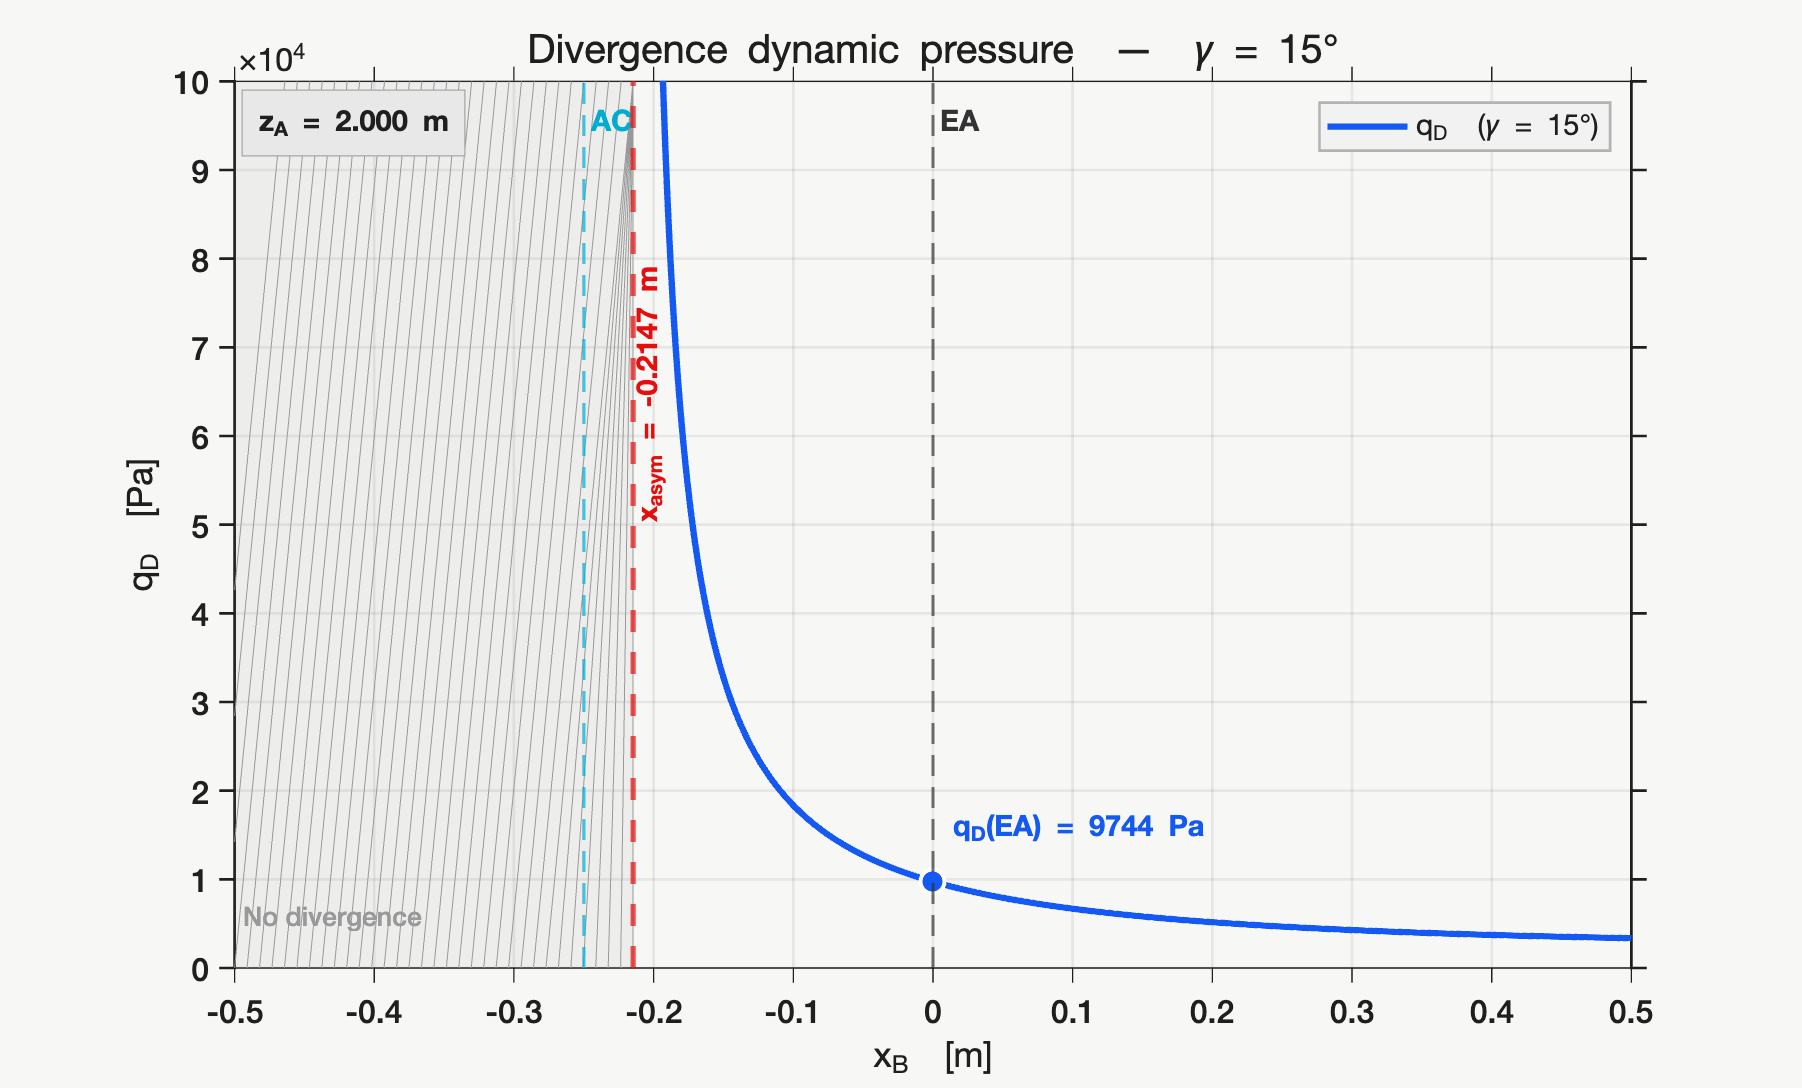

%% ── Divergence dynamic pressure vs x_B at γ = 15 deg ──────────────────
gamma_deg = 15;
gamma     = deg2rad(gamma_deg);
x_B_vec   = linspace(-c/2, c/2, 4000);

%% Compute
qD_vec = arrayfun(@(xB) q_D(gamma, xB), x_B_vec);
qD_vec(~isfinite(qD_vec) | qD_vec <= 0) = NaN;

den_qD = @(xB) K_S11(gamma, xB)*K_A2 - K_S12(gamma, xB)*K_A1;
x_asym = -den_qD(0) / (den_qD(1) - den_qD(0));
qD_EA  = q_D(gamma, 0);

x_EA = 0;
x_AC = -c/4;

%% ── Palette ────────────────────────────────────────────────────────────
BG      = [0.97 0.97 0.96];
FG      = [0.12 0.12 0.12];
C_LEFT  = [0.08 0.35 0.95];   % bleu électrique
C_ASYM  = [0.90 0.05 0.05];   % rouge pur
C_AC    = [0.00 0.68 0.82];   % cyan vif
C_EA    = [0.20 0.20 0.20];   % quasi-noir
HATCH_C = [0.60 0.60 0.60];
Y_MAX   = 1e5;

%% ── Figure / axes ──────────────────────────────────────────────────────
fig = figure('Color', BG, 'Position', [100 80 960 580]);
ax  = axes('Parent', fig, ...
    'Color',     BG,      ...
    'XColor',    FG,      ...
    'YColor',    FG,      ...
    'GridColor', [0 0 0], ...
    'GridAlpha', 0.07,    ...
    'Box',       'on',    ...
    'LineWidth',  1.0,    ...
    'FontName',  'Helvetica Neue', ...
    'FontSize',   12,     ...
    'TickDir',   'out');
hold on; grid on;

xl = [min(x_B_vec), max(x_B_vec)];
yl = [0, Y_MAX];
xlim(xl); ylim(yl);

%% ── Hatch "no divergence" ───────────────────────────────────────────────
if x_asym > xl(1)
    x_L = xl(1);
    x_R = min(x_asym, xl(2));

    patch([x_L x_R x_R x_L], [yl(1) yl(1) yl(2) yl(2)], ...
          HATCH_C, 'FaceAlpha', 0.10, 'EdgeColor', 'none', ...
          'HandleVisibility', 'off');

    nH = 32;
    dx = (x_R - x_L) / nH;
    for k = -3:nH
        x0 = x_L + k*dx;
        x1 = min(x0 + 0.22*(x_R - x_L), x_R);
        line([x0 x1], [yl(1) yl(2)], ...
            'Color', [HATCH_C 0.40], 'LineWidth', 0.35, ...
            'Clipping', 'on', 'HandleVisibility', 'off');
    end

    text(x_L + 0.02*(x_R - x_L), yl(1) + 0.06*(yl(2)-yl(1)), ...
        'No divergence', ...
        'FontName','Helvetica Neue','FontSize',10, ...
        'Color', HATCH_C, 'HorizontalAlignment','left');
end

%% ── Courbes ─────────────────────────────────────────────────────────────
eps_x = (xl(2)-xl(1)) * 2e-3;
idx_L = x_B_vec <  x_asym - eps_x;
idx_R = x_B_vec >  x_asym + eps_x;

plot(x_B_vec(idx_L), qD_vec(idx_L), ...
    'Color', C_LEFT, 'LineWidth', 2.4, ...
    'DisplayName', sprintf('q_D  (\\gamma = %.0f°)', gamma_deg));
plot(x_B_vec(idx_R), qD_vec(idx_R), ...
    'Color', C_LEFT, 'LineWidth', 2.4, ...
    'HandleVisibility', 'off');

%% ── Verticales de référence ─────────────────────────────────────────────
xline(x_asym, 'Color', C_ASYM, 'LineStyle', '--', 'LineWidth', 2.0, ...
    'HandleVisibility', 'off');
xline(x_EA,   'Color', C_EA,   'LineStyle', '--', 'LineWidth', 1.2, ...
    'HandleVisibility', 'off');
xline(x_AC,   'Color', C_AC,   'LineStyle', '--', 'LineWidth', 1.2, ...
    'HandleVisibility', 'off');

%% ── Labels EA / AC ──────────────────────────────────────────────────────
text(x_EA + 0.005*(xl(2)-xl(1)), yl(2)*0.978, 'EA', ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', C_EA, 'HorizontalAlignment','left','VerticalAlignment','top');

text(x_AC + 0.005*(xl(2)-xl(1)), yl(2)*0.978, 'AC', ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', C_AC, 'HorizontalAlignment','left','VerticalAlignment','top');

%% ── Label asymptote : vertical, à droite de la ligne ───────────────────
text(x_asym + 0.025*(xl(2)-xl(1)), yl(1) + 0.5*(yl(2)-yl(1)), ...
    sprintf('x_{asym} = %.4f m', x_asym), ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', C_ASYM, ...
    'HorizontalAlignment','left','VerticalAlignment','bottom', ...
    'Rotation', 90);

%% ── Marqueur q_D(EA) + label à droite ──────────────────────────────────
if isfinite(qD_EA) && qD_EA > 0 && qD_EA <= Y_MAX
    plot(x_EA, qD_EA, 'o', ...
        'MarkerSize',  9, ...
        'MarkerFaceColor', C_LEFT, ...
        'MarkerEdgeColor', [1 1 1], ...
        'LineWidth',   1.5, ...
        'HandleVisibility', 'off');

    text(x_EA + 0.012*(xl(2)-xl(1)), qD_EA + 0.06*(yl(2)-yl(1)), ...
        sprintf('q_D(EA) = %.4g Pa', qD_EA), ...
        'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
        'Color', C_LEFT, ...
        'HorizontalAlignment','left','VerticalAlignment','middle');
end

%% ── Boîte z_A ───────────────────────────────────────────────────────────
text(xl(1) + 0.015*(xl(2)-xl(1)), yl(2)*0.975, ...
    sprintf('z_A = %.3f m', z_A), ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', FG, 'HorizontalAlignment','left','VerticalAlignment','top', ...
    'BackgroundColor',[0.91 0.91 0.91],'EdgeColor',[0.65 0.65 0.65],'Margin',5);

%% ── Axes labels / titre / légende ──────────────────────────────────────
xlabel('x_B  [m]',  'Color',FG,'FontName','Helvetica Neue','FontSize',13);
ylabel('q_D  [Pa]', 'Color',FG,'FontName','Helvetica Neue','FontSize',13);
title(sprintf('Divergence dynamic pressure  —  \\gamma = %.0f°', gamma_deg), ...
    'Color',FG,'FontName','Helvetica Neue','FontSize',15,'FontWeight','normal');

lg = legend('Location','northeast','FontSize',11,'FontName','Helvetica Neue');
lg.TextColor = FG;
lg.EdgeColor = [0.70 0.70 0.70];
lg.Color     = [0.95 0.95 0.95];

# Control Effectiveness EC�(q) and Identification of the Control Reversal Pressure qC

This section focuses exclusively on the variation of the control effectiveness EC� with the dynamic pressure q, for several values of the strut angle γ, at a certain xB. The purpose of the code is to visualize how the aeroelastic response modifies the authority of the control surface as aerodynamic loading increases.

For each angle, the curve EC(q) is plotted over a truncated pressure range, and the region corresponding to **control reversal** is highlighted, that is when EC<0.

The code also detects, for each configuration, the corresponding **control reversal pressure** qC�, defined as the first value of dynamic pressure at which EC� changes sign from positive to negative.

This plot therefore provides a direct comparison of the effect of γ on both the loss of control effectiveness and the onset of reversal.

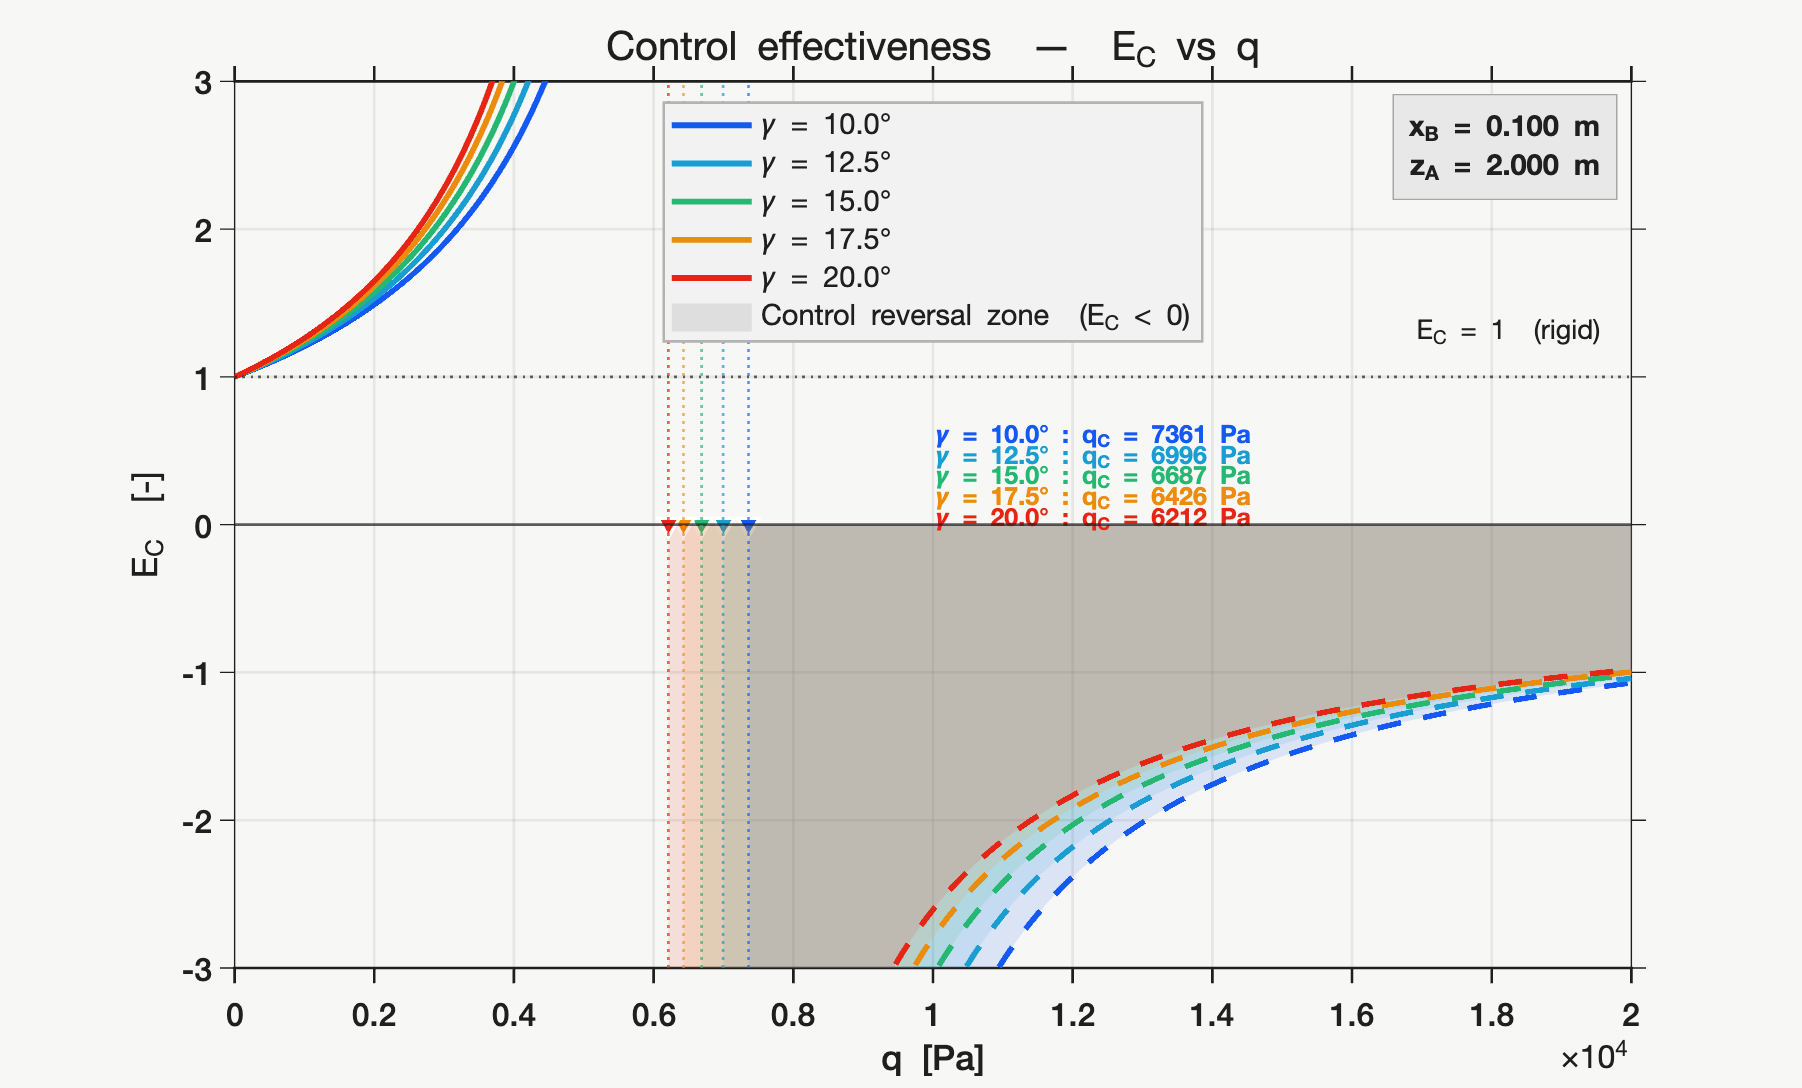

%% ── Control effectiveness E_C vs q for several γ values ────────────────

x_B_fixed  = 0.1;                        % [m]
q_max_plot = 2e4;                        % [Pa]  tronquage demandé
q_vec      = linspace(0, q_max_plot, 5000);
gamma_degs = [10, 12.5, 15, 17.5, 20];   % [deg]

%% ── Palette ─────────────────────────────────────────────────────────────
BG      = [0.97 0.97 0.96];
FG      = [0.12 0.12 0.12];

% Couleurs par gamma : dégradé bleu → orange
CMAP = [ ...
    0.08  0.35  0.95;   % γ = 10°
    0.10  0.62  0.82;   % γ = 12.5°
    0.15  0.72  0.45;   % γ = 15°
    0.92  0.55  0.05;   % γ = 17.5°
    0.90  0.15  0.08;   % γ = 20°
];

Y_MIN = -3;
Y_MAX =  3;

%% ── Figure / axes ───────────────────────────────────────────────────────
fig = figure('Color', BG, 'Position', [100 80 960 580]);
ax  = axes('Parent', fig, ...
    'Color',     BG,      ...
    'XColor',    FG,      ...
    'YColor',    FG,      ...
    'GridColor', [0 0 0], ...
    'GridAlpha', 0.07,    ...
    'Box',       'on',    ...
    'LineWidth', 1.0,     ...
    'FontName',  'Helvetica Neue', ...
    'FontSize',  12,      ...
    'TickDir',   'out');
hold on; grid on;

xl = [0, q_max_plot];
yl = [Y_MIN, Y_MAX];
xlim(xl); ylim(yl);

%% ── Lignes de référence ────────────────────────────────────────────────
yline(0, 'Color', [FG 0.4], 'LineStyle', '-', 'LineWidth', 1, ...
    'HandleVisibility', 'off');

yline(1, 'Color', [FG 0.25], 'LineStyle', ':', 'LineWidth', 1, ...
    'HandleVisibility', 'off');

text(xl(2)*0.98, 1 + 0.03*(Y_MAX-Y_MIN), 'E_C = 1  (rigid)', ...
    'FontName','Helvetica Neue','FontSize',10,'Color',[FG 0.5], ...
    'HorizontalAlignment','right','VerticalAlignment','bottom');

%% ── Préallocation ──────────────────────────────────────────────────────
h = gobjects(numel(gamma_degs), 1);

%% ── Tracé pour chaque γ ─────────────────────────────────────────────────
for i = 1:numel(gamma_degs)
    gd  = gamma_degs(i);
    g   = deg2rad(gd);
    col = CMAP(i,:);

    % Calcul E_C
    EC_vec = arrayfun(@(q) E_C(g, x_B_fixed, q), q_vec);
    EC_vec(~isfinite(EC_vec)) = NaN;

    % Pression de divergence
    qD_i = q_D(g, x_B_fixed);

    % Masque valide
    valid_mask = isfinite(EC_vec);

    % -------- Zone de control reversal : E_C < 0 --------
    neg_mask = valid_mask & (EC_vec < 0);

    dmask   = diff([false, neg_mask, false]);
    i_start = find(dmask == 1);
    i_end   = find(dmask == -1) - 1;

    for k = 1:numel(i_start)
        idx = i_start(k):i_end(k);

        x_patch = [q_vec(idx), fliplr(q_vec(idx))];
        y_patch = [EC_vec(idx), zeros(size(idx))];

        patch('XData', x_patch, 'YData', y_patch, ...
              'FaceColor', col, ...
              'FaceAlpha', 0.12, ...
              'EdgeColor', 'none', ...
              'HandleVisibility', 'off');
    end

    % -------- Tracé de la courbe --------
    if isfinite(qD_i) && qD_i > 0 && qD_i <= xl(2)
        eps_q = (xl(2)-xl(1)) * 2e-3;
        idx_L = q_vec <  qD_i - eps_q;
        idx_R = q_vec >  qD_i + eps_q;

        h(i) = plot(q_vec(idx_L), EC_vec(idx_L), ...
            'Color', col, 'LineWidth', 2.2, ...
            'DisplayName', sprintf('\\gamma = %.1f°', gd));

        plot(q_vec(idx_R), EC_vec(idx_R), ...
            'Color', col, 'LineWidth', 2.2, 'LineStyle', '--', ...
            'HandleVisibility', 'off');

        xline(qD_i, 'Color', [col 0.35], 'LineStyle', ':', ...
            'LineWidth', 1.0, 'HandleVisibility', 'off');
    else
        h(i) = plot(q_vec, EC_vec, ...
            'Color', col, 'LineWidth', 2.2, ...
            'DisplayName', sprintf('\\gamma = %.1f°', gd));
    end

    % -------- q_C : premier passage de E_C > 0 vers E_C < 0 --------
    sign_change = find( ...
        valid_mask(1:end-1) & valid_mask(2:end) & ...
        (EC_vec(1:end-1) > 0) & (EC_vec(2:end) < 0), ...
        1, 'first');

    if ~isempty(sign_change)
        q1 = q_vec(sign_change);
        q2 = q_vec(sign_change + 1);
        E1 = EC_vec(sign_change);
        E2 = EC_vec(sign_change + 1);

        % interpolation linéaire
        q_rev = q1 - E1 * (q2 - q1) / (E2 - E1);

        % marqueur sur E_C = 0
        plot(q_rev, 0, 'v', ...
            'MarkerSize', 7, ...
            'MarkerFaceColor', col, ...
            'MarkerEdgeColor', [1 1 1], ...
            'LineWidth', 1.2, ...
            'HandleVisibility', 'off');

        % étiquettes empilées autour de (10000, 0.5)
        x_txt = 10000;
        y_txt = 0.6 - (i-1)*0.14;

        text(x_txt, y_txt, ...
            sprintf('\\gamma = %.1f° : q_C = %.0f Pa', gd, q_rev), ...
            'Color', col, ...
            'FontSize', 9.5, ...
            'FontName', 'Helvetica Neue', ...
            'HorizontalAlignment', 'left', ...
            'VerticalAlignment', 'middle', ...
            'FontWeight', 'bold');
    end
end

%% ── Boîte paramètres (x_B et z_A) ──────────────────────────────────────
text(xl(2) - 0.02*(xl(2)-xl(1)), yl(2) - 0.03*(yl(2)-yl(1)), ...
    sprintf('x_B = %.3f m\nz_A = %.3f m', x_B_fixed, z_A), ...
    'FontName','Helvetica Neue','FontSize',11,'FontWeight','bold', ...
    'Color', FG, ...
    'HorizontalAlignment','right','VerticalAlignment','top', ...
    'BackgroundColor',[0.91 0.91 0.91], ...
    'EdgeColor',     [0.65 0.65 0.65], ...
    'Margin', 5);

%% ── Légende zone reversal ──────────────────────────────────────────────
patch([NaN NaN NaN NaN], [NaN NaN NaN NaN], [0.3 0.3 0.3], ...
      'FaceAlpha', 0.12, 'EdgeColor', 'none', ...
      'DisplayName', 'Control reversal zone  (E_C < 0)');

%% ── Axes labels / titre / légende ──────────────────────────────────────
xlabel('q  [Pa]',  'Color',FG,'FontName','Helvetica Neue','FontSize',13);
ylabel('E_C  [-]', 'Color',FG,'FontName','Helvetica Neue','FontSize',13);
title('Control effectiveness  —  E_C vs q', ...
    'Color',FG,'FontName','Helvetica Neue','FontSize',15,'FontWeight','normal');

lg = legend('Location','north','FontSize',11,'FontName','Helvetica Neue');
lg.TextColor = FG;
lg.EdgeColor = [0.70 0.70 0.70];
lg.Color     = [0.95 0.95 0.95];

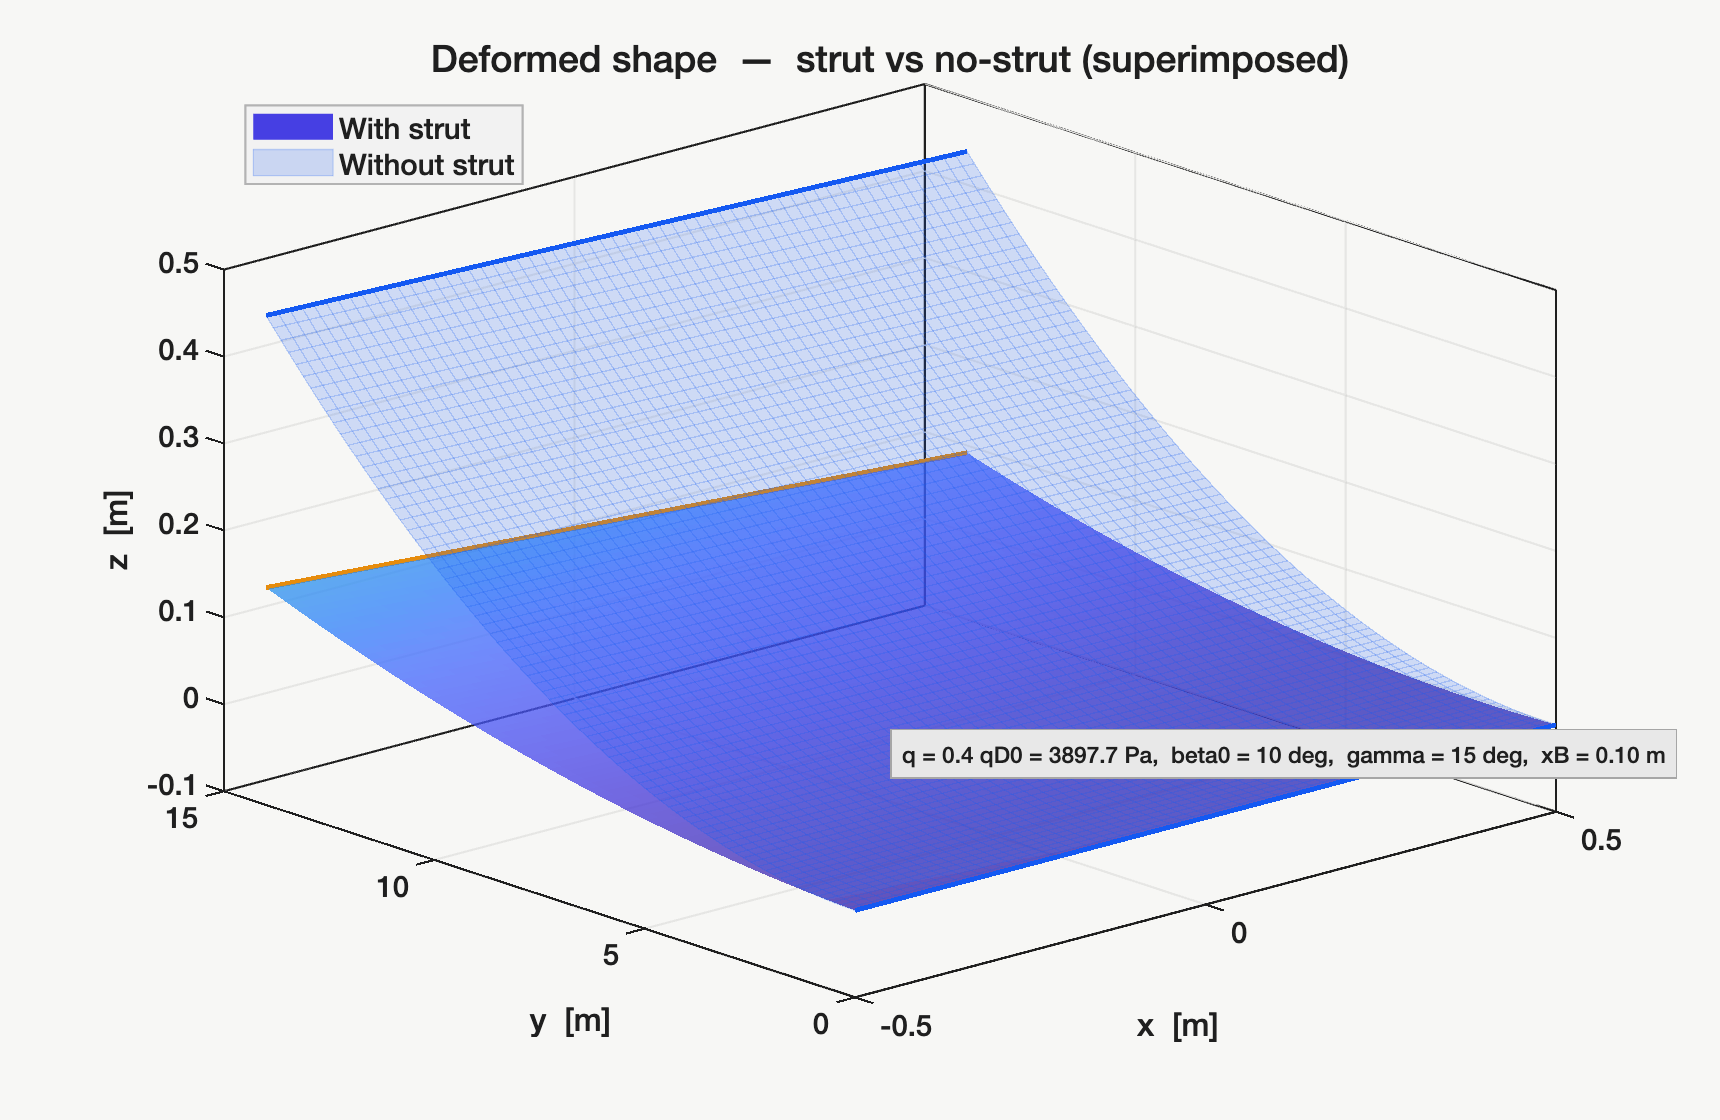

%% ── Wing deformed shape -- Strut effect ───────────────────────────────

%% Paramètres
beta0_deg      = 10;
beta0          = deg2rad(beta0_deg);
gamma_deg_plot = 15;
gamma_plot     = deg2rad(gamma_deg_plot);
x_B_plot       = 0.1;

%% q_D sans strut (EA = 0)
K_S11_ns = @(g, xB) 4*EJ/b^3;
K_S12_ns = @(g, xB) 0;
K_S22_ns = @(g, xB) GJ/b;

q_D_ns = (K_S11_ns(gamma_plot, x_B_plot) * K_S22_ns(gamma_plot, x_B_plot) ...
         - K_S12_ns(gamma_plot, x_B_plot)^2) ...
         / (K_S11_ns(gamma_plot, x_B_plot) * K_A2 ...
         - K_S12_ns(gamma_plot, x_B_plot) * K_A1);

q_eval = 0.4 * q_D_ns;

%% Grille (x, y)
Nx    = 60; Ny = 80;
x_vec = linspace(-c/2, c/2, Nx);
y_vec = linspace(0, b, Ny);
[XX, YY] = meshgrid(x_vec, y_vec);

%% Déformées
z_strut = compute_z( ...
    K_S11(gamma_plot, x_B_plot), ...
    K_S12(gamma_plot, x_B_plot), ...
    K_S22(gamma_plot, x_B_plot), ...
    q_eval, K_A, F_a, beta0, XX, YY, b);

z_ns = compute_z( ...
    K_S11_ns(gamma_plot, x_B_plot), ...
    K_S12_ns(gamma_plot, x_B_plot), ...
    K_S22_ns(gamma_plot, x_B_plot), ...
    q_eval, K_A, F_a, beta0, XX, YY, b);

dz = z_strut - z_ns;

%% Palette commune
BG   = [0.97 0.97 0.96];
FG   = [0.12 0.12 0.12];
FNT  = 'Helvetica Neue';
C_ST = [0.90 0.55 0.05];
C_NS = [0.08 0.35 0.95];

param_str = sprintf( ...
    'q = 0.4 qD0 = %.1f Pa,  beta0 = %.0f deg,  gamma = %.0f deg,  xB = %.2f m', ...
    q_eval, beta0_deg, gamma_deg_plot, x_B_plot);

%% Coupes
y_cuts = [b/4, b/2, 3*b/4, b];
x_cuts = [-c/4, 0, c/4];

CMAP_y = [0.08 0.35 0.95;
          0.10 0.70 0.30;
          0.90 0.55 0.05;
          0.90 0.15 0.08];

CMAP_x = [0.08 0.35 0.95;
          0.90 0.15 0.08;
          0.15 0.72 0.35];

%% ════════════════════════════════════════════════════════════════════════
%  FIG 1 — Superposition 3D
%% ════════════════════════════════════════════════════════════════════════
fig1 = figure('Color', BG, 'Position', [60 60 860 560]);
ax1  = setup_ax3d(fig1, FNT, FG, BG);

s1 = surf(ax1, XX, YY, z_strut, 'EdgeColor', 'none', 'FaceAlpha', 0.75);
colormap(ax1, parula);

s2 = surf(ax1, XX, YY, z_ns, ...
    'EdgeColor', C_NS, 'EdgeAlpha', 0.22, ...
    'FaceColor', C_NS, 'FaceAlpha', 0.18);

plot3(ax1, x_vec, zeros(1,Nx),  z_strut(1,:),  'Color', C_ST, 'LineWidth', 1.8);
plot3(ax1, x_vec, zeros(1,Nx),  z_ns(1,:),     'Color', C_NS, 'LineWidth', 1.8);
plot3(ax1, x_vec, b*ones(1,Nx), z_strut(end,:),'Color', C_ST, 'LineWidth', 1.8);
plot3(ax1, x_vec, b*ones(1,Nx), z_ns(end,:),   'Color', C_NS, 'LineWidth', 1.8);

legend(ax1, [s1, s2], {'With strut', 'Without strut'}, ...
    'Location', 'northwest', 'FontSize', 11, 'FontName', FNT, ...
    'TextColor', FG, 'EdgeColor', [0.70 0.70 0.70], 'Color', [0.95 0.95 0.95]);
add_annot3d(ax1, x_vec, y_vec, z_strut, param_str, FNT, FG);
title(ax1, 'Deformed shape  —  strut vs no-strut (superimposed)', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');

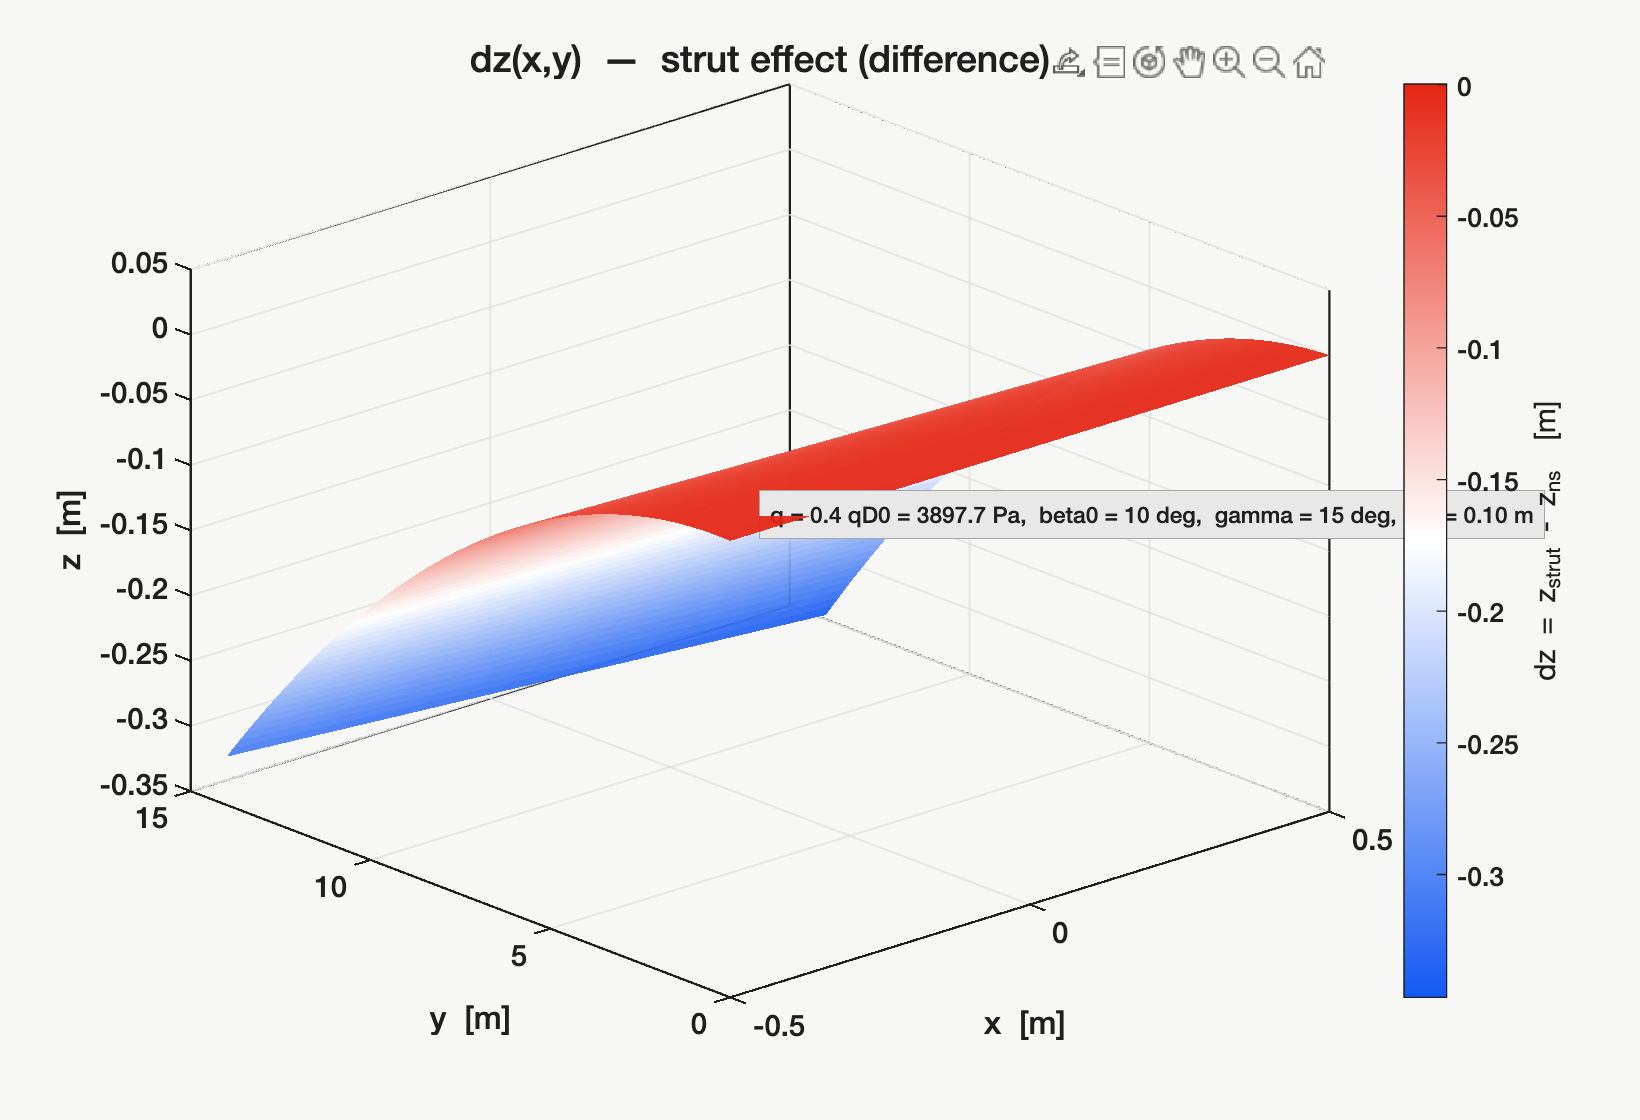


%% ════════════════════════════════════════════════════════════════════════
%  FIG 2 — Difference 3D  dz
%% ════════════════════════════════════════════════════════════════════════
fig2 = figure('Color', BG, 'Position', [80 60 820 560]);
ax2  = setup_ax3d(fig2, FNT, FG, BG);
surf(ax2, XX, YY, dz, 'EdgeColor', 'none', 'FaceAlpha', 0.93);
colormap(ax2, bluewhitered(256));
cb2 = colorbar(ax2); style_cb(cb2, 'dz = z_{strut} - z_{ns}  [m]', FNT, FG);
add_annot3d(ax2, x_vec, y_vec, dz, param_str, FNT, FG);
title(ax2, 'dz(x,y)  —  strut effect (difference)', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');

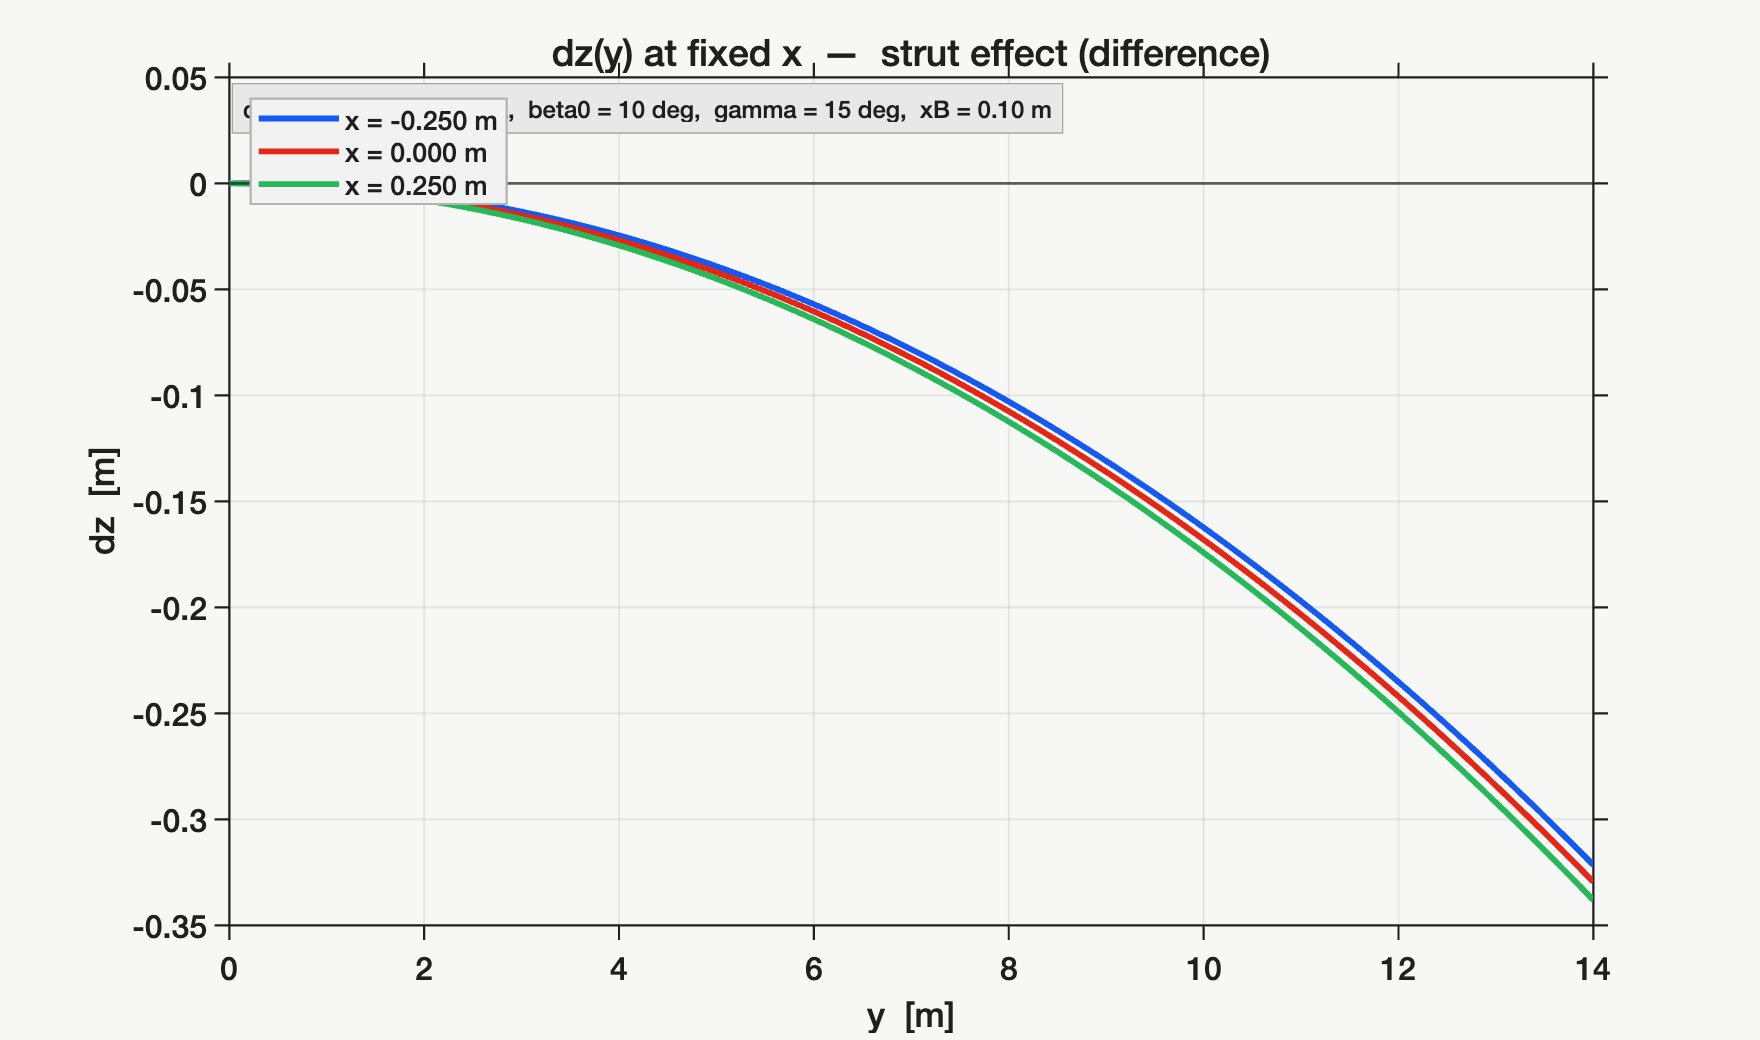


%% ════════════════════════════════════════════════════════════════════════
%  FIG 3 — Coupes 2D plan (y,z)  dz a x fixe
%% ════════════════════════════════════════════════════════════════════════
fig3 = figure('Color', BG, 'Position', [100 60 880 520]);
ax3  = setup_ax2d(fig3, FNT, FG, BG);
yline(ax3, 0, 'Color', [FG 0.35], 'LineWidth', 1.0, 'HandleVisibility', 'off');

for k = 1:numel(x_cuts)
    [~, ix] = min(abs(x_vec - x_cuts(k)));
    plot(ax3, y_vec, dz(:,ix), '-', 'Color', CMAP_x(k,:), 'LineWidth', 2.2, ...
        'DisplayName', sprintf('x = %.3f m', x_cuts(k)));
end

xlabel(ax3, 'y  [m]',  'Color', FG, 'FontName', FNT, 'FontSize', 13);
ylabel(ax3, 'dz  [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
title(ax3, 'dz(y) at fixed x  —  strut effect (difference)', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');
add_legend(ax3, FNT, FG);
add_box_2d(ax3, param_str, FNT, FG);

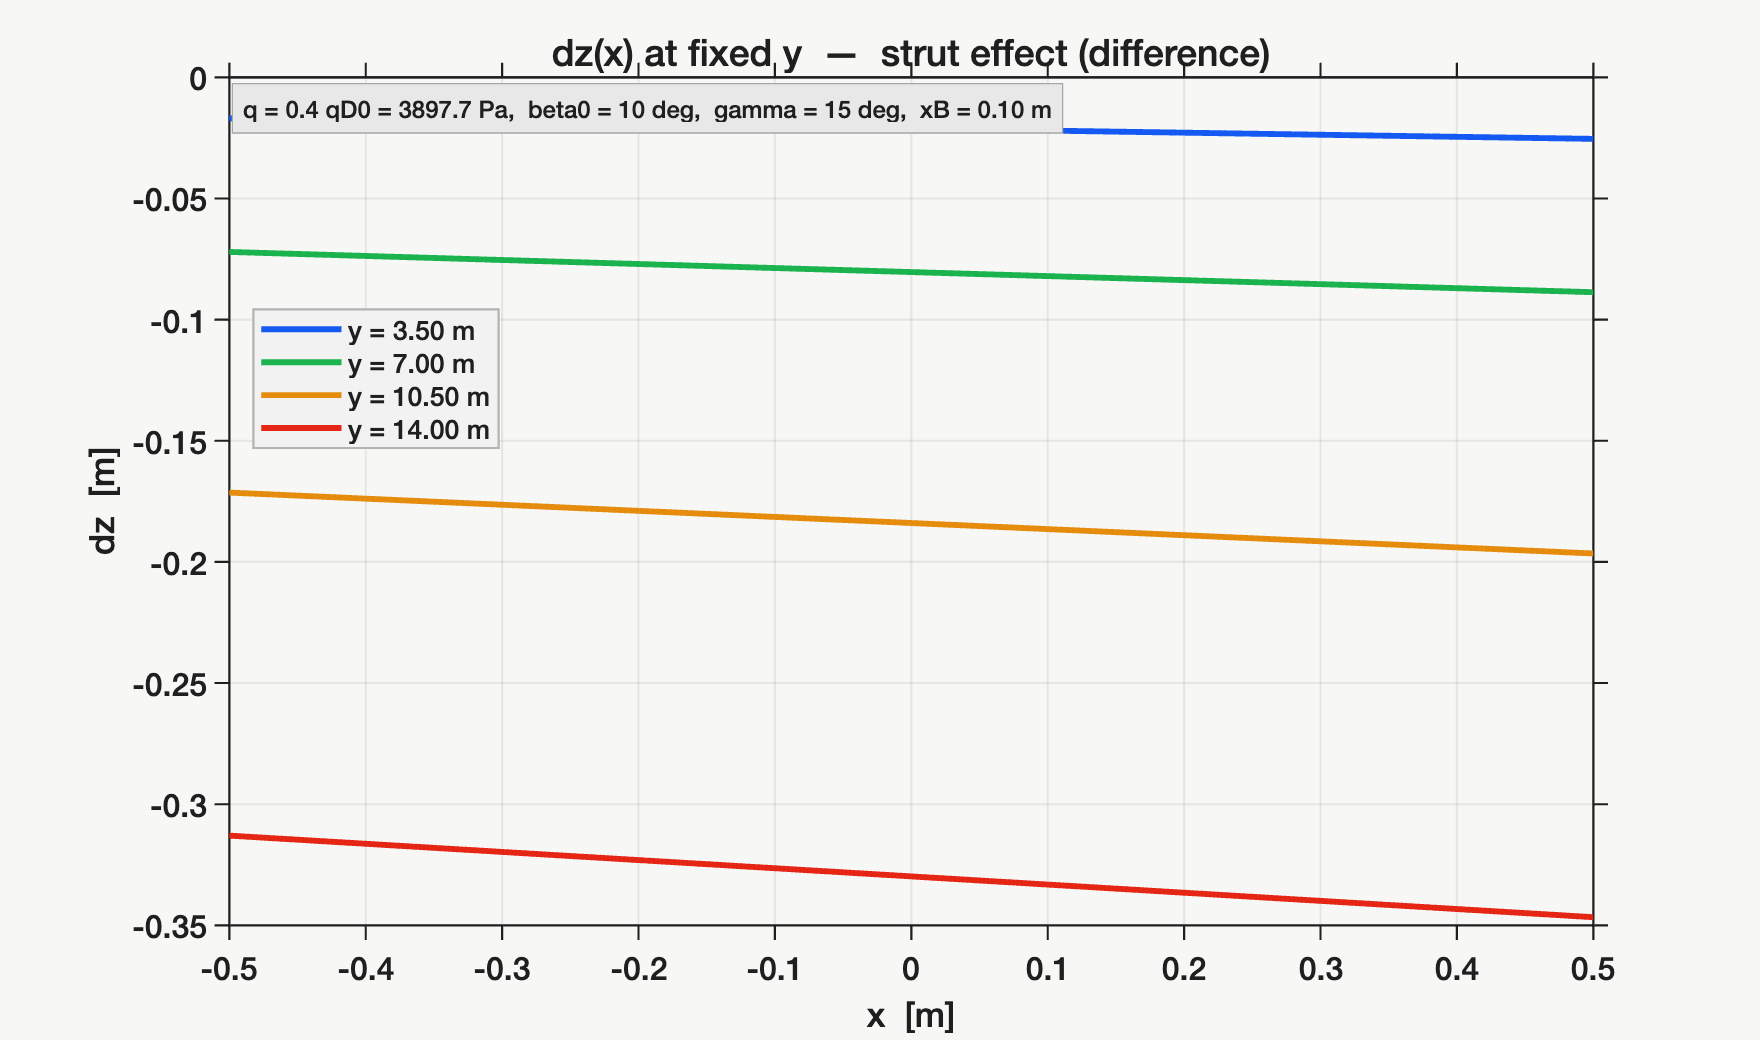


%% ════════════════════════════════════════════════════════════════════════
%  FIG 4 — Coupes 2D plan (x,z)  dz a y fixe
%% ════════════════════════════════════════════════════════════════════════
fig4 = figure('Color', BG, 'Position', [120 60 880 520]);
ax4  = setup_ax2d(fig4, FNT, FG, BG);
yline(ax4, 0, 'Color', [FG 0.35], 'LineWidth', 1.0, 'HandleVisibility', 'off');

for k = 1:numel(y_cuts)
    [~, iy] = min(abs(y_vec - y_cuts(k)));
    plot(ax4, x_vec, dz(iy,:), '-', 'Color', CMAP_y(k,:), 'LineWidth', 2.2, ...
        'DisplayName', sprintf('y = %.2f m', y_cuts(k)));
end

xlabel(ax4, 'x  [m]',  'Color', FG, 'FontName', FNT, 'FontSize', 13);
ylabel(ax4, 'dz  [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 13);
title(ax4, 'dz(x) at fixed y  —  strut effect (difference)', ...
    'Color', FG, 'FontName', FNT, 'FontSize', 14, 'FontWeight', 'normal');
add_legend(ax4, FNT, FG);
add_box_2d(ax4, param_str, FNT, FG);



%% ════════════════════════════════════════════════════════════════════════
%  LOCAL FUNCTIONS
%% ════════════════════════════════════════════════════════════════════════

function Z = compute_z(Ks11, Ks12, Ks22, q, K_A, F_a, beta, XX, YY, b)
    K_TOT = [Ks11 - q*K_A(1,1),  Ks12 - q*K_A(1,2);
             Ks12 - q*K_A(2,1),  Ks22 - q*K_A(2,2)];
    phi       = K_TOT \ (q * beta * F_a);
    phi_w     = phi(1);
    phi_theta = phi(2);
    Z = (YY/b).^2 * phi_w  -  XX .* (YY/b) * phi_theta;
end

function cmap = bluewhitered(n)
    if nargin < 1, n = 256; end
    h    = floor(n/2);
    c1   = interp1([0 1], [0.08 0.35 0.95; 1 1 1], linspace(0,1,h));
    c2   = interp1([0 1], [1 1 1; 0.90 0.15 0.08], linspace(0,1,n-h));
    cmap = [c1; c2];
end

function ax = setup_ax3d(fig, FNT, FG, BG)
    ax = axes('Parent', fig, ...
        'Color',     BG,      ...
        'XColor',    FG,      ...
        'YColor',    FG,      ...
        'ZColor',    FG,      ...
        'FontName',  FNT,     ...
        'FontSize',  11,      ...
        'TickDir',   'out',   ...
        'GridAlpha', 0.07,    ...
        'GridColor', [0 0 0], ...
        'Box',       'on',    ...
        'LineWidth', 0.8);
    hold(ax, 'on'); grid(ax, 'on'); view(ax, -42, 28);
    xlabel(ax, 'x  [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 12);
    ylabel(ax, 'y  [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 12);
    zlabel(ax, 'z  [m]', 'Color', FG, 'FontName', FNT, 'FontSize', 12);
end

function ax = setup_ax2d(fig, FNT, FG, BG)
    ax = axes('Parent', fig, ...
        'Color',     BG,      ...
        'XColor',    FG,      ...
        'YColor',    FG,      ...
        'FontName',  FNT,     ...
        'FontSize',  12,      ...
        'TickDir',   'out',   ...
        'GridAlpha', 0.07,    ...
        'GridColor', [0 0 0], ...
        'Box',       'on',    ...
        'LineWidth', 0.8);
    hold(ax, 'on'); grid(ax, 'on');
end

function style_cb(cb, lbl, FNT, FG)
    cb.Label.String   = lbl;
    cb.Label.FontName = FNT;
    cb.Label.FontSize = 11;
    cb.Color          = FG;
end

function add_annot3d(ax, x_vec, y_vec, Z, str, FNT, FG)
    zmax = max(Z(:), [], 'omitnan');
    if ~isfinite(zmax), zmax = 0; end
    text(ax, min(x_vec)*0.80, min(y_vec) + 0.04*(max(y_vec)-min(y_vec)), zmax, ...
        str, ...
        'FontName',        FNT,              ...
        'FontSize',        8.5,              ...
        'Color',           FG,               ...
        'Interpreter',     'none',           ...
        'BackgroundColor', [0.91 0.91 0.91], ...
        'EdgeColor',       [0.65 0.65 0.65], ...
        'Margin',          4);
end

function add_legend(ax, FNT, FG)
    lg           = legend(ax, 'Location', 'northwest', ...
                          'FontSize', 10, 'FontName', FNT);
    lg.TextColor = FG;
    lg.EdgeColor = [0.70 0.70 0.70];
    lg.Color     = [0.95 0.95 0.95];
end

function add_box_2d(ax, str, FNT, FG)
    xl = xlim(ax);
    yl = ylim(ax);
    text(ax, xl(1) + 0.01*(xl(2)-xl(1)), yl(2) - 0.02*(yl(2)-yl(1)), ...
        str, ...
        'FontName',            FNT,              ...
        'FontSize',            9,                ...
        'Color',               FG,               ...
        'Interpreter',         'none',           ...
        'HorizontalAlignment', 'left',           ...
        'VerticalAlignment',   'top',            ...
        'BackgroundColor',     [0.91 0.91 0.91], ...
        'EdgeColor',           [0.65 0.65 0.65], ...
        'Margin',              4);
end